## 分散共分散行列とデータの分布

最後に，分散共分散行列$V$について詳しく見ていきましょう．分散共分散行列はデータの分布を効率よく把握するのに便利です．このセクションでは分散共分散行列とデータの分布の関係について詳しく見ていきます．まずは，改めて分散共分散行列$V$を成分で表記してみます．


$$V=\left\lbrack \begin{array}{cc}
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \\
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 
\end{array}\right\rbrack$$


$V$の1行1列目の成分は中心化されたデータ行列$X$の1行目（一つ目の変数${{\mathrm{x}}_1 }^{\left(i\right)}$）の分散そのものです．同様に2行2列目の成分はデータ行列$X$の2行目（もう一つの変数${{\mathrm{x}}_2 }^{\left(i\right)}$）の分散です．（いずれの変数も中心化されているので平均がゼロになることに注意してください．さて，1行2列目と2行1列目の成分はどちらも同じものです．これは変数${{\mathrm{x}}_1 }^{\left(i\right)}$と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の共分散と言われる指標で，二つの変数の関係を表します．共分散の符号で場合分けして考えてみましょう．

- $\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} >0$: 変数${{\mathrm{x}}_1 }^{\left(i\right)}$が（平均より）大きいとき変数${{\mathrm{x}}_2 }^{\left(i\right)}$も（ゼロ＝平均より）大きい，または変数${{\mathrm{x}}_1 }^{\left(i\right)}$が（ゼロ＝平均より）小さいとき変数${{\mathrm{x}}_2 }^{\left(i\right)}$も（平均より）小さい．共分散が（ゼロよりも）大きいほど，これらの傾向は顕著になります．

- $\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} <0$: 変数${{\mathrm{x}}_1 }^{\left(i\right)}$が（平均より）大きいとき変数${{\mathrm{x}}_2 }^{\left(i\right)}$は（ゼロ＝平均より）**小さい**，または変数${{\mathrm{x}}_1 }^{\left(i\right)}$が（ゼロ＝平均より）小さいとき変数${{\mathrm{x}}_2 }^{\left(i\right)}$は（平均より）**大きい**．共分散が（ゼロよりも）小さくなるほど，これらの傾向は顕著になります．

- $\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} =0$: 上記のような関係がない．

これらの関係は相関関係数に似ています．じつは共分散と相関係数には以下のような関係があります．


$$\rho_{{\mathrm{x}}_1 {\mathrm{x}}_2 } =\frac{{\sigma_{{\mathrm{x}}_1 {\mathrm{x}}_2 } }^2 }{\sigma_{{\mathrm{x}}_1 } \sigma_{{\mathrm{x}}_2 } }$$


ここで，$\rho_{{\mathrm{x}}_1 {\mathrm{x}}_2 }$は変数${{\mathrm{x}}_1 }^{\left(i\right)}$と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の相関係数を表します．また，${\sigma_{{\mathrm{x}}_1 {\mathrm{x}}_2 } }^2$は変数${{\mathrm{x}}_1 }^{\left(i\right)}$と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の共分散（${\sigma_{{\mathrm{x}}_1 {\mathrm{x}}_2 } }^2 =\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}$）です．$\sigma_{{\mathrm{x}}_1 }$と$\sigma_{{\mathrm{x}}_2 }$はそれぞれ，変数${{\mathrm{x}}_1 }^{\left(i\right)}$と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の標準偏差（分散の平方根：$\sigma_{{\mathrm{x}}_1 } =\sqrt{\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2 }$，$\sigma_{{\mathrm{x}}_2 } =\sqrt{\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 }$）です．

#### 分散共分散行列によるデータ構造の要約

それでは，分散共分散行列とデータの分布の関係を具体的に見ていきたいと思います．MATLABのStatistical and Machine Learning Toolboxに用意されているmvnrnd関数を使います．mvnrnd関数は多変量正規分布に基づく乱数を発生させます．その際に，各変数の平均値と分散共分散行列を指定することで，任意の乱数セットを発生させることができます．この関数を使って，特定の分散共分散行列を与えたときのデータの分布をグラフにして確認して行きたいと思います．ここでも視覚化を用意にするために二変数のデータセットを作っていきたいと思います（サンプル数は$100$とします）．データの中心化が必要ないように，各変数の平均は予めゼロにしておきます．まずはヘルプを見てみましょう．

help mvnrnd

mvnrnd - 多変量正規分布の乱数

    この MATLAB 関数 は、平均 MU と共分散 SIGMA を使用した多変量正規分布から選択した乱数ベクトルの、n 行 d 列の行列 R を返します。

    R = mvnrnd(MU,SIGMA)
    r = mvnrnd(MU,SIGMA,cases)

    参考 <a href="https://localhost:31515/static/help/stats/mvncdf.html">mvncdf</a>, <a href="https://localhost:31515/static/help/stats/mvnpdf.html">mvnpdf</a>, <a href="https://localhost:31515/static/help/stats/normrnd.html">normrnd</a>

    mvnrnd のリファレンス ページ



平均値は一つ目の引数MUで指定します．分散共分散行列は二つ目の引数SIGMAで指定します．

#### 非対角成分he

#### の影響

まずは，各変数の分散（分散共分散行列の対角成分）を$1$に固定して，共分散（分散共分散行列の非対角成分）を変化させたときに，データの散布図がどう変化するかを見ていきます．

【共分散が$0$のとき】

共分散が$0$のとき，すなわち分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

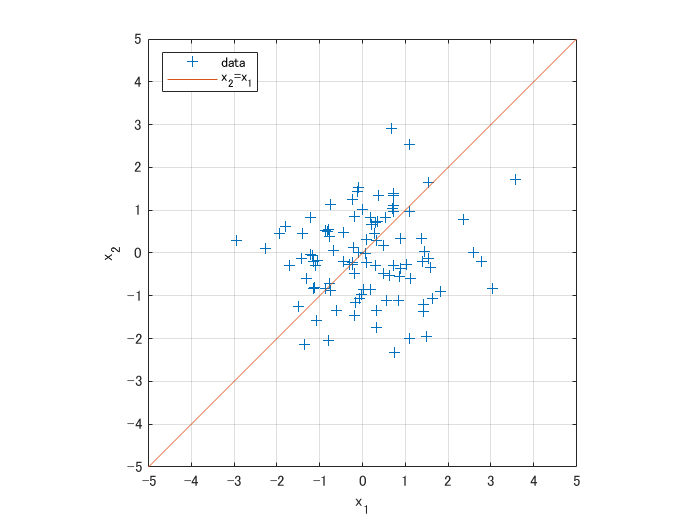

m = [0 0];
covar = 0; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 0; 0 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1','Location','northwest');

データは原点$O\left(0,0\right)$を中心にどの方向にもほぼ均等に分布しているようにみえます．赤い実線はデータの${\mathrm{x}}_2 ={\mathrm{x}}_2$で表される直線です．

【共分散が$0\ldotp 5$のとき】

共分散が$0\ldotp 5$のとき，すなわち分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & 0\ldotp 5\\
05 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

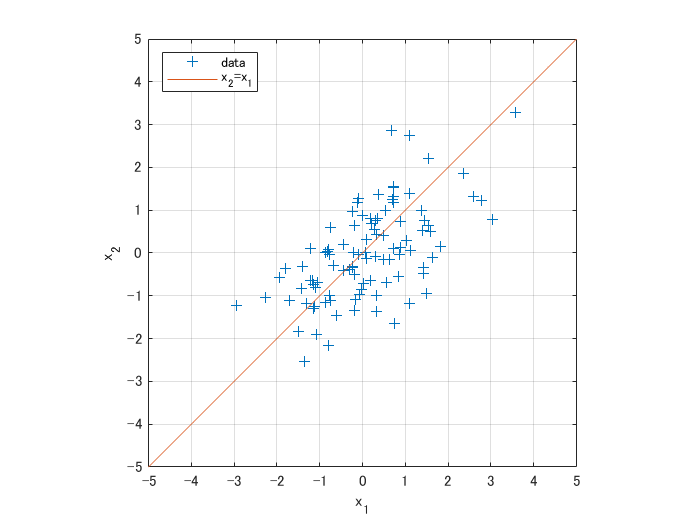

m = [0 0];
covar = 0.5; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 0.5; 0.5 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1','Location','northwest');

さきほどの散布図と比べて，データが直線${\mathrm{x}}_2 ={\mathrm{x}}_1$のまわりに集まっているのが見て取れます．

【共分散が$0\ldotp 75$のとき】

共分散が$0\ldotp 75$のとき，すなわち分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & 0\ldotp 75\\
0\ldotp 75 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

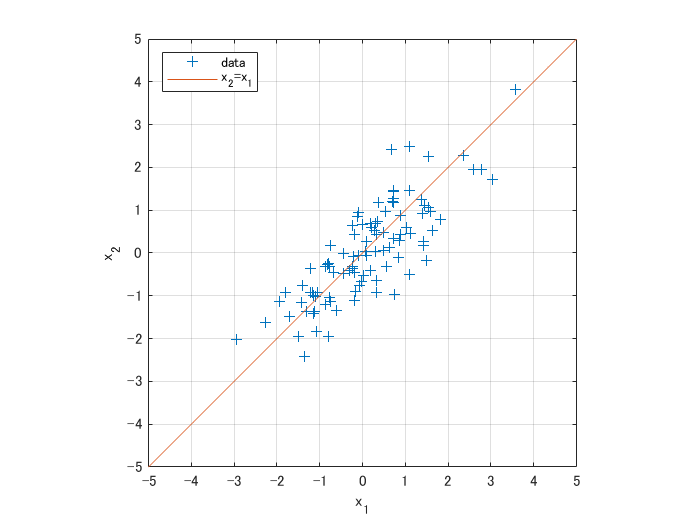

m = [0 0];
covar = 0.75; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 0.75; 0.75 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1','Location','northwest');

共分散が$0\ldotp 5$のときよりも，データがさらに直線に沿って分布するようになりました．．

【共分散が$1$のとき】

共分散が$1$のとき，すなわち分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

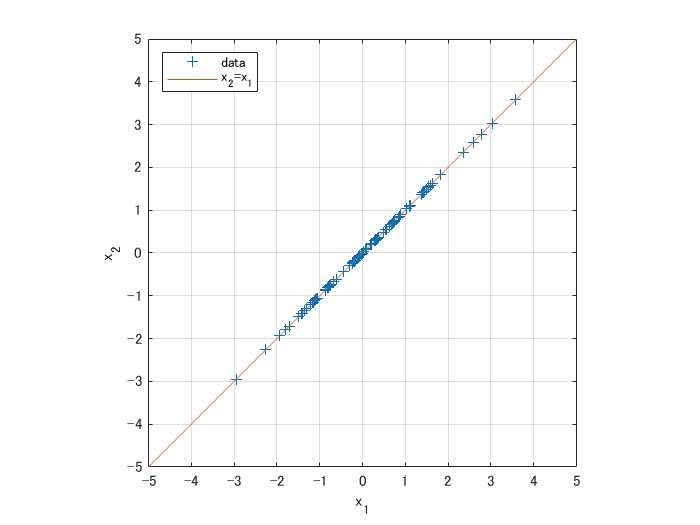

m = [0 0];
covar = 1; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 1; 1 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1','Location','northwest');

共分散を$1$にすると，データは直線${\mathrm{x}}_2 ={\mathrm{x}}_1$上に分布するようになりました．上記のように，（対角成分を$1$に固定して）共分散の値をゼロから$1$に近づけていくにつれ，データが直線${\mathrm{x}}_2 ={\mathrm{x}}_1$に近づいていきます．前述したように，共分散は変数${{\mathrm{x}}_1 }^{\left(i\right)}$と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の相関の程度と関係しています．対角成分を$1$に固定した場合，共分散（または相関）の大きさは直線${\mathrm{x}}_2 ={\mathrm{x}}_1$への当てはまりの良さを表します．当てはまりの良さ（つまり相関係数の大きさ）とは，直線への集中の度合い（相関係数が大きいほど直線に集中する）として視覚的に理解しておくのは有用です．

対角成分を$1$に固定し，共分散をゼロから$-1$に変化させたときは，直線${\mathrm{x}}_2 =-{\mathrm{x}}_1$への当てはまりの良さとして理解することができます．以下に共分散が$-0\ldotp 5$の場合と$-1$の場合を示しますので，確認してください．

【共分散が$-0\ldotp 5$のとき】

分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & -0\ldotp 5\\
-0\ldotp 5 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

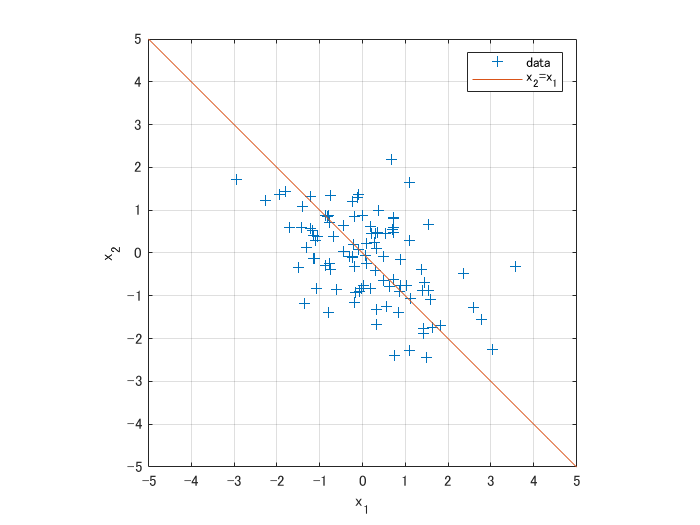

m = [0 0];
covar = -0.5; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 -0.5; -0.5 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = -t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1');

【共分散が$-1$のとき】

分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

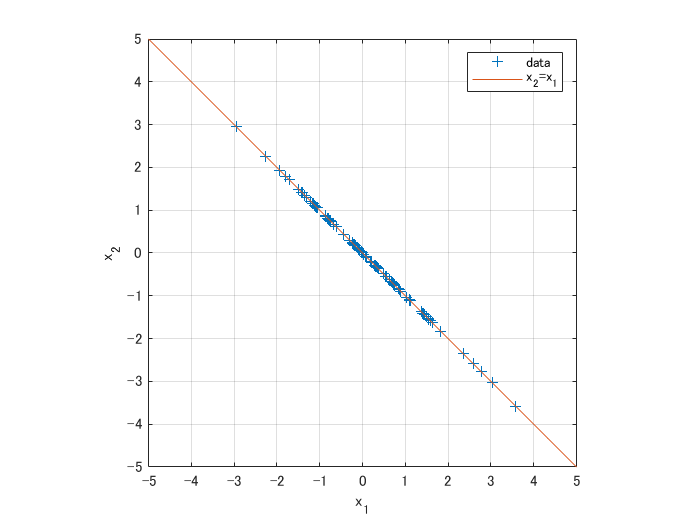

m = [0 0];
covar = -1; % 共分散
s = [1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure('Name','Data from V=[1 -1; -1 1]');
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = -t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1');

#### 対角成分の影響

次に対角成分の影響をしらべるために，共分散（非対角成分）と変数${{\mathrm{x}}_2 }^{\left(i\right)}$の分散の値をそれぞれ$1$に固定して，変数${{\mathrm{x}}_1 }^{\left(i\right)}$の分散の値（分散共分散行列の1行1列目）を変えて行きます．

【変数${{\mathrm{x}}_1 }^{\left(i\right)}$の分散が$1$のとき】

分散共分散行列が$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

m = [0 0];
covar = 1;
varx1 = 1;
s = [varx1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure();
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
% b = [ones(size(data,1),1) data(:,1)]\data(:,2); % b = X\Y
% reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(2),b(1));
% annotation('textbox',[.25 .5 .3 .3],'String',reg_str,'FitBoxToText','on','BackgroundColor','w');
% t1 = -5:0.01:5;
% t2 = b(2)*t1+b(1);
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
legend('data','x_2=x_1','Location','northwest');

赤い実線は引き続き${\mathrm{x}}_1 ={\mathrm{x}}_2$の直線を表します．さきほど見たように，データ点はすべて直線上に分布します．

【変数${{\mathrm{x}}_1 }^{\left(i\right)}$の分散が$2$のとき】

分散共分散行列が$\left\lbrack \begin{array}{cc}
2 & 1\\
1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

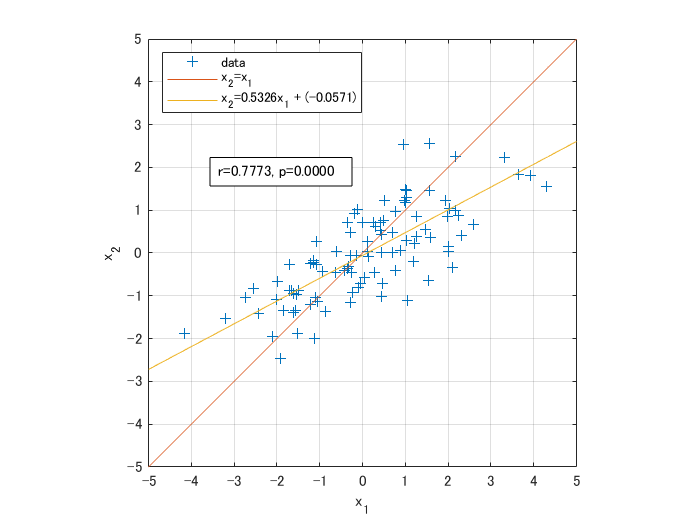

m = [0 0];
covar = 1;
varx1 = 2;
s = [varx1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure();
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
d1 = data(:,1); d2 = data(:,2);
b = polyfit(d1,d2,1);
d2fit = polyval(b,d1); % d2fit = b(1)*d1 + b(2)
d2resid = d2 - d2fit;
SSresid = sum(d2resid.^2);
t1_reg = -5:0.01:5;
t2_reg = b(1)*t1_reg+b(2);
plot(t1_reg,t2_reg);
reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(1),b(2));
legend('data','x_2=x_1',reg_str,'Location','northwest');
[rhos,pvals]=corrcoef(data);
corr_str = sprintf('r=%0.4f, p=%0.4f',rhos(1,2),pvals(1,2));
annotation('textbox',[.3 .4 .3 .3],'String',corr_str,'FitBoxToText','on','BackgroundColor','w');

${\mathrm{x}}_1 ={\mathrm{x}}_2$の直線（赤実線）に加えて，オレンジ色でデータの回帰直線を追加しました．回帰式は${\mathrm{x}}_2 =0\ldotp 5236{\mathrm{x}}_1 -0\ldotp 0571$でした．${\mathrm{x}}_2$切片は原点近くを通っています．回帰直線の傾きはおよそ$0\ldotp 5$です．データの分布を見てみると，縦方向に比べて横方向に大きく広がっているのがわかります．分散共分散行列の対角成分は変数${\mathrm{x}}_1$および${\mathrm{x}}_2$の分散をそれぞれ表します．いま，変数${\mathrm{x}}_1$の分散（$=2$）は${\mathrm{x}}_2$の分散（$=1$）の倍になっているので，横方向の広がりは縦方向のおよそ$2$倍になっているはずです．実際に計算してみましょう．

var(data,1)

ans =     2.6753    1.2561


変数${\mathrm{x}}_1$の分散（$=2\ldotp 6753$）は変数${\mathrm{x}}_2$の分散（=1.2561）のおよそ$2$倍になっています．グラフ内の小枠にはデータの相関係数及びその$p$値も示しています．変数${\mathrm{x}}_1$および${\mathrm{x}}_2$の相関係数は$0\ldotp 7773$と，両者に高い相関がありました（$p<0\ldotp 001$）．

【変数${{\mathrm{x}}_1 }^{\left(i\right)}$の分散が$4$のとき】

次に，分散共分散行列が$\left\lbrack \begin{array}{cc}
4 & 1\\
1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

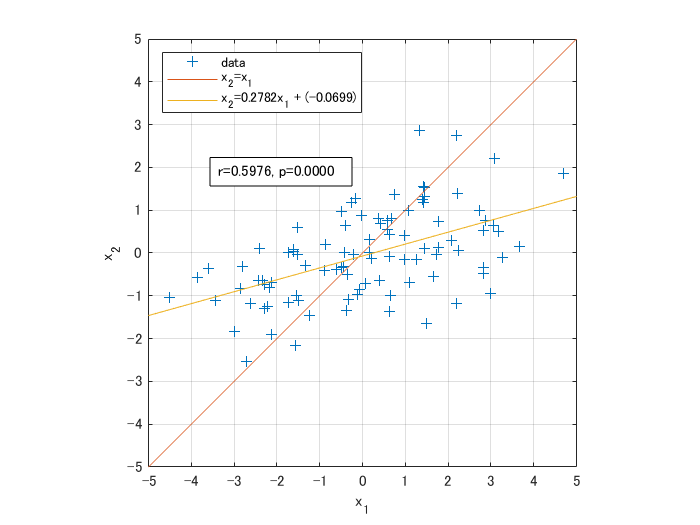

m = [0 0];
covar = 1;
varx1 = 4;
s = [varx1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure();
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
xlabel('x_1'); ylabel('x_2');
t1 = -5:0.051:5;
t2 = t1;
hold on; plot(t1,t2);
d1 = data(:,1); d2 = data(:,2);
b = polyfit(d1,d2,1);
d2fit = polyval(b,d1); % d2fit = b(1)*d1 + b(2)
d2resid = d2 - d2fit;
SSresid = sum(d2resid.^2);
t1_reg = -5:0.01:5;
t2_reg = b(1)*t1_reg+b(2);
plot(t1_reg,t2_reg);
reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(1),b(2));
legend('data','x_2=x_1',reg_str,'Location','northwest');
[rhos,pvals]=corrcoef(data);
corr_str = sprintf('r=%0.4f, p=%0.4f',rhos(1,2),pvals(1,2));
annotation('textbox',[.3 .4 .3 .3],'String',corr_str,'FitBoxToText','on','BackgroundColor','w');

今回の回帰式は${\mathrm{x}}_2 =0\ldotp 2782{\mathrm{x}}_1 -0\ldotp 0699$でした．${\mathrm{x}}_2$切片はやはり原点近くを通っています．データの分布はさきほどよりもさらに横方向に大きく広がっているのがわかります．それに対応するように，回帰直線の傾きはおよそ$0\ldotp 2782$となっています．いま，変数${\mathrm{x}}_1$の分散（$=4$）は${\mathrm{x}}_2$の分散（$=1$）の$4$倍になっているので，横方向の広がりは縦方向のおよそ$4$倍になっているはずです．実際に計算してみましょう．

var(data,1)

ans =     5.3506    1.1600


変数${\mathrm{x}}_1$の分散（$=5\ldotp 3506$）は変数${\mathrm{x}}_2$の分散（=1.16）のおよそ$4\ldotp 6$倍になっています．回帰直線へのデータの当てはまりの良さはさきほどにくらべて悪くなっているように見えます．実際に，変数${\mathrm{x}}_1$および${\mathrm{x}}_2$の相関係数は$0\ldotp 5976$と，さきほど（$0\ldotp 7773$）よりも低下していますが，依然として高い水準で相関しています（$p<0\ldotp 001$）．

【変数${{\mathrm{x}}_1 }^{\left(i\right)}$の分散が$8$のとき】

最後に，分散共分散行列が$\left\lbrack \begin{array}{cc}
8 & 1\\
1 & 1
\end{array}\right\rbrack$となるときのデータの散布図を下図に示します．

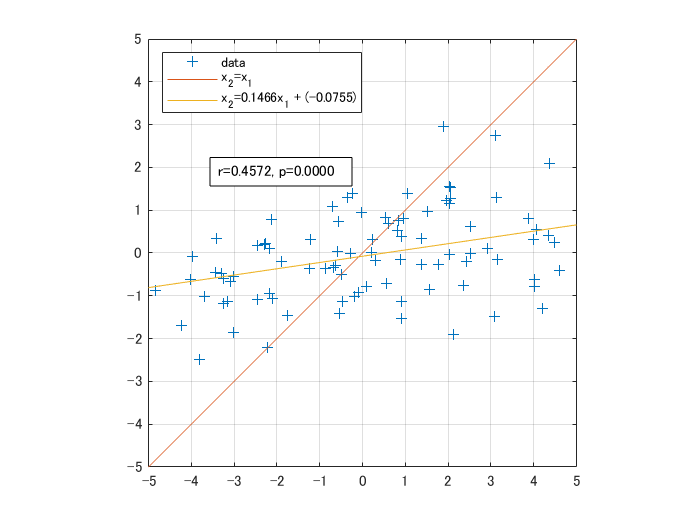

m = [0 0];
covar = 1;
varx1 = 8;
s = [varx1 covar; covar 1];
nsamples = 100;
rng default  % For reproducibility
data = mvnrnd(m,s,nsamples);
figure();
plot(data(:,1),data(:,2),'+');
axis([-5 5 -5 5]); axis square; grid on;
t1 = -5:0.01:5;
t2 = t1;
hold on; plot(t1,t2);
d1 = data(:,1); d2 = data(:,2);
b = polyfit(d1,d2,1);
d2fit = polyval(b,d1); % d2fit = b(1)*d1 + b(2)
d2resid = d2 - d2fit;
SSresid = sum(d2resid.^2);
t1_reg = -5:0.01:5;
t2_reg = b(1)*t1_reg+b(2);
plot(t1_reg,t2_reg);
reg_str = sprintf('x_2=%0.4fx_1 + (%0.4f)',b(1),b(2));
legend('data','x_2=x_1',reg_str,'Location','northwest');
[rhos,pvals]=corrcoef(data);
corr_str = sprintf('r=%0.4f, p=%0.4f',rhos(1,2),pvals(1,2));
annotation('textbox',[.3 .4 .3 .3],'String',corr_str,'FitBoxToText','on','BackgroundColor','w');

今回の回帰式は${\mathrm{x}}_2 =0\ldotp 1466{\mathrm{x}}_1 -0\ldotp 0755$でした．${\mathrm{x}}_2$切片はやはり原点近くを通っています．データの分布はさきほどの二つの例よりもさらに横方向に大きく広がっています．また，回帰直線の傾きはおよそ$0\ldotp 1466$となっています．変数${\mathrm{x}}_1$の分散（$=8$）は${\mathrm{x}}_2$の分散（$=1$）の$8$倍になっているので，横方向の広がりは縦方向のおよそ$8$倍になっているはずです．実際に計算してみましょう．

var(data,1)

ans =    10.7013    1.0999


変数${\mathrm{x}}_1$の分散（$=10\ldotp 7013$）は変数${\mathrm{x}}_2$の分散（$=1\ldotp 0999$）のおよそ$9\ldotp 7$倍になっています．予想の$8$倍よりも大きくなっています．ランダムに発生させたデータなのでたまたま大きな値になったのかもしれません．mvnrnd関数を用いた乱数発生を$1000$回繰り返して，縦軸と横軸の分散比の平均で比べてみましょう．

nRepeats = 1000;
vars = zeros(nRepeats,2);
for iRep = 1:nRepeats
    data = mvnrnd([0 0],[8 1;1 1],100);
    vars(iRep,:) = var(data);
end
mean(vars)

ans =     8.0141    0.9989


変数${\mathrm{x}}_1$の分散の平均（$=8\ldotp 0141$）は変数${\mathrm{x}}_2$の分散の平均（$=0\ldotp 9989$）のおよそ$8$倍になっています．分散共分散行列から予想される値になりました．さて，回帰直線へのデータの当てはまりの良さはさきほどの二例にくらべてさらに悪くなっているように見えます．実際に，変数${\mathrm{x}}_1$および${\mathrm{x}}_2$の相関係数は$0\ldotp 4572$と，さきほどよりも低下していますが，依然として高い水準で相関しています（$p<0\ldotp 001$）．

以上，みてきたように分散共分散行列の対角成分は，回帰直線の傾きと強い関係があります．一方の非対角成分は，直線への当てはまりの良さ――つまり相関係数――と強い関係があります．